## **Φόρτωση εικόνας**

clc; clear; close all;
%  Ρύθμιση διαδρομής εικόνας
imgPath = fullfile('Images','Ασκηση 1','moon.jpg');

## Βοηθητικές συναρτήσεις

function F = DFT_rowcol(img)
    % Υλοποίηση 2‑D DFT μέσω σειριακής 1‑D FFT
    [M,N] = size(img);
    F = zeros(M,N);
    % FFT κατά γραμμές
    for r = 1:M
        F(r,:) = fft( img(r,:) );
    end
    % FFT κατά στήλες
    for c = 1:N
        F(:,c) = fft( F(:,c) );
    end
end

function img = IDFT_rowcol(F)
    % Υλοποίηση 2‑D IDFT με 1‑D IFFT (αντίστροφο του DFT_rowcol)
    [M,N] = size(F);
    img = zeros(M,N);
    % IFFT κατά στήλες
    for c = 1:N
        img(:,c) = ifft( F(:,c) );
    end
    % IFFT κατά γραμμές
    for r = 1:M
        img(r,:) = ifft( img(r,:) );
    end
end


## Preproccessing & Φάσμα

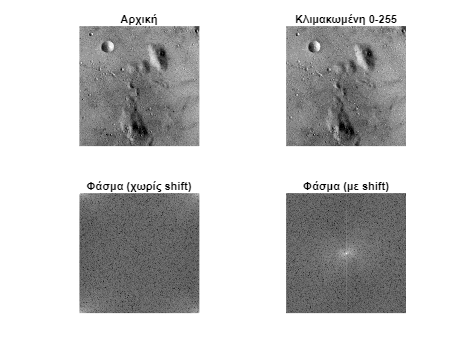

%  Βήμα 1 : Προεπεξεργασία – κλιμάκωση [0,255] & κεντράρισμα φάσματος

I0 = imread(imgPath);                % αρχική εικόνα (πιθανόν uint8)
I0 = rgb2gray(I0);                   % αν τυχόν είναι RGB
I  = im2double(I0);                  % [0,1]
I  = 255 * mat2gray(I);              % [0,255] floating
Iu = uint8(round(I));                % για απεικόνιση

% 2‑D DFT (row‑column) χωρίς κέντρο
F_rc = DFT_rowcol(double(I));        % η helper συνάρτηση στο τέλος

% Μεταφορά DC στο κέντρο με fftshift
Fshift = fftshift(F_rc);


figure('Name','Step 1 – Pre‑processing','NumberTitle','off');
subplot(2,2,1), imshow(I0,[]),      title('Αρχική');
subplot(2,2,2), imshow(Iu,[]),      title('Κλιμακωμένη 0‑255');
subplot(2,2,3), imshow(log(1+abs(F_rc)),[]), title('Φάσμα (χωρίς shift)');
subplot(2,2,4), imshow(log(1+abs(Fshift)),[]), title('Φάσμα (με ­shift)');

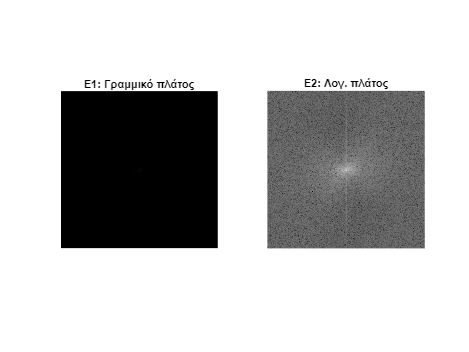


figure('Name','Step 2 – Amplitude Spectrum','NumberTitle','off');
subplot(1,2,1), imshow(abs(Fshift),[]),        title('E1: Γραμμικό πλάτος');
subplot(1,2,2), imshow(log(1+abs(Fshift)),[]), title('E2: Λογ. πλάτος');

## Manual DFT  & Φιλτράρισμα



% 7. Υλοποίηση 2D DFT με μέθοδο σειρών-στηλών
[M,N] = size(I_stretched);
F_row = zeros(M,N);
for i = 1:M
    F_row(i,:) = fft(I_stretched(i,:));
end
F_manual = zeros(M,N);
for j = 1:N
    F_manual(:,j) = fft(F_row(:,j));
end

% 8. Υπολογισμός πλάτους μετασχηματισμού
Mag = abs(F_manual);

% 9. Γραμμική απεικόνιση πλάτους
Mag_linear = Mag / max(Mag(:));

% 10. Λογαριθμική απεικόνιση πλάτους
Mag_log = log(1 + Mag);

% 11. Οπτικοποίηση γραμμικού & λογαριθμικού φάσματος
figure('Name','Φάσματα row–column','NumberTitle','off');
subplot(1,2,1);
imshow(Mag_linear, []);
title('Γραμμικό Φάσμα (row–column)');
subplot(1,2,2);
imshow(Mag_log, []);
title('Λογαριθμικό Φάσμα (row–column)');

## Φίλτρο και Spectrums

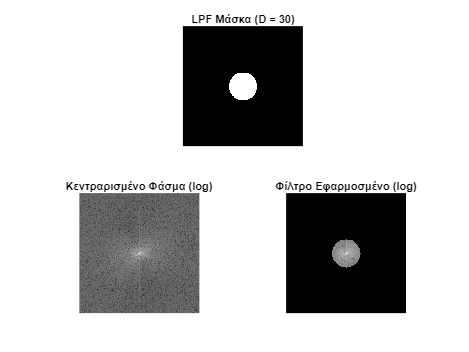

[M,N] = size(I);
[u,v] = meshgrid( (-N/2):(N/2-1), (-M/2):(M/2-1) );
D = sqrt(u.^2 + v.^2);
D0 = 30;                                % διάμετρος ζώνης διέλευσης
H  = double( D <= D0 );                 % ιδανικό κυκλικό LPF (mask)

F_filt = Fshift .* H;                   % εφαρμογή φίλτρου

% ---- Εικόνες Βήματος 3 -------------------------------------------------
figure('Name','Step 3 – Filtering','NumberTitle','off');
subplot(2,2,1:2), imshow(H,[]),              title(sprintf('LPF Μάσκα (D = %d)',D0));
subplot(2,2,3), imshow(log(1+abs(Fshift)),[]), title('Κεντραρισμένο Φάσμα (log)');
subplot(2,2,4), imshow(log(1+abs(F_filt)),[]), title('Φίλτρο Εφαρμοσμένο (log)');

## IDFT & Τελική Απεικόνιση

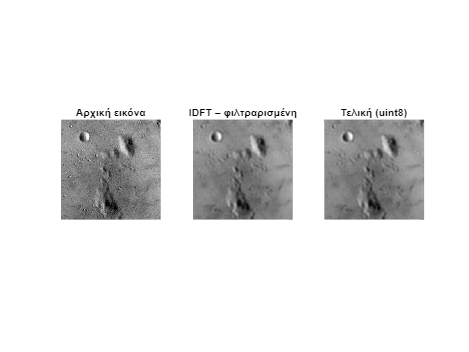

% Αντιστροφή fftshift πριν την IDFT
F_ifft = ifftshift(F_filt);

% Inverse DFT (στήλες‑γραμμές)
I_rec = real( IDFT_rowcol(F_ifft) );

% -----------------------------------------------------------------------
%  Βήμα 5 : Αντιστροφή μεταφοράς DC & τελικό rescaling
% -----------------------------------------------------------------------
I_rec = 255 * mat2gray(I_rec);         % επανακλιμάκωση [0,255]
I_rec_u8 = uint8(round(I_rec));

figure('Name','Step 4‑5 – Spatial Results','NumberTitle','off');
subplot(1,3,1), imshow(I0,[]),        title('Αρχική εικόνα');
subplot(1,3,2), imshow(I_rec,[]),     title('IDFT – φιλτραρισμένη');
subplot(1,3,3), imshow(I_rec_u8,[]),  title('Τελική (uint8)');